We set up a $5\times 5$ triangular matrix with prescribed eigenvalues on its diagonal.

lambda = [1 -0.75 0.6 -0.4 0];
A = triu(ones(5),1) + diag(lambda); 
format long

We run inverse iteration with the shift $s=0.7$ and take the final estimate as our ``exact'' answer to observe the convergence. 

[gamma,x] = inviter(A,0.7,30);
eigval = gamma(end)

eigval =    0.599999999999999


As expected, the eigenvalue that was found is the one closest to $0.7$. The convergence is again linear.

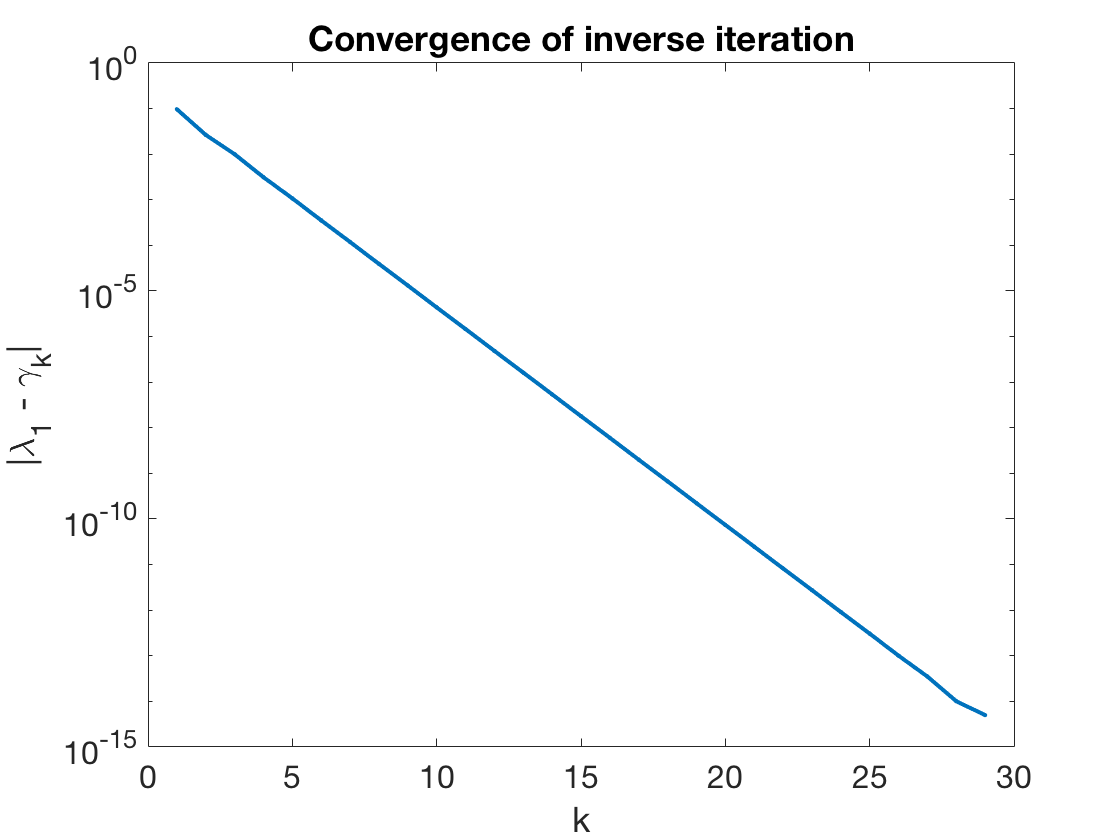

err = eigval - gamma;
semilogy(abs(err),'.-')
title('Convergence of inverse iteration')   % ignore this line
xlabel('k'), ylabel('|\lambda_1 - \gamma_k|')    % ignore this line

The observed linear convergence rate is found from the data. 

observed_rate = err(26)/err(25)

observed_rate =   -0.328141977544368


In the numbering of this example, the eigenvalue closest to $s=0.7$ is $\lambda_3$ and the next-closest is $\lambda_1$.

theoretical_rate = (lambda(3)-0.7) / (lambda(1)-0.7)

theoretical_rate =   -0.333333333333333
